# Digital Signal Processing Lab 4

# Syed Asghar Abbas Zaidi 07201

## Exercise 1

In digital signal processing, various reconstruction filters are used to reconstruct continuous-time signals from their sampled versions. We will be analyzing the concepts utilized, compare the filters, and discuss their advantages and disadvantages.

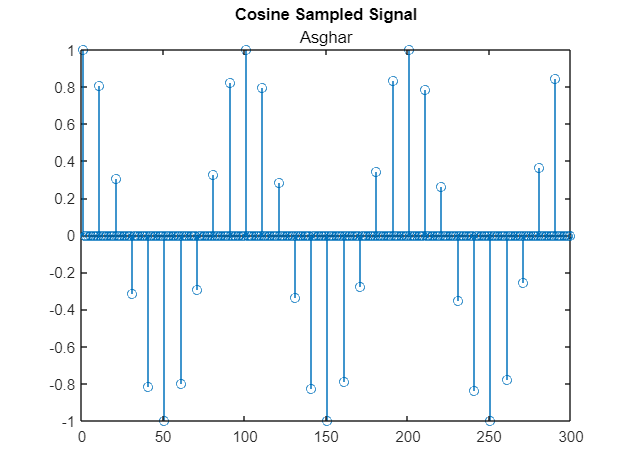

f0=3; % signal frequency
 K=10; % sampling factor
 fs=K*f0; % sampling frequency 
Ts=1/fs; % sampling period
 %Why not do it "1", we are getting perfectly fine samples.
 M=10; % M-1 is number of padded zeros
 Cycles=3; % Number of cycles we want to plot
 %0.111.. = 1/(3*3)  
Tmax=1/f0*Cycles; % Maximum time value
 time=linspace(0,Tmax,round(fs*Tmax*M)); % time scale
 dt=time(2)-time(1); % Minimum time step
 xt=cos(2*pi*f0*time); % Sampling signal
 xSn=zeros(1,length(xt)); % Sampled signal 
%So, essentially, this line implements the sampling process by taking samples 
% from the continuous signal xt at regular intervals determined by M and assigns
 %  them to the array xSn, effectively creating a sampled version of the signal.
 xSn (1:M:end)=xt(1:M:end); % Sampled signal
 figure; stem(xSn);
 title('Cosine Sampled Signal','Asghar')

## Exercise 2 (Zero Order Hold) 

This filter approximates the continuous-time signal between samples by  holding the value of the last sample. The impulse response of the ZOH  filter is a rectangular pulse with duration `Ts`. The `filter` function in MATLAB is used to perform the convolution between the ZOH  impulse response and the sampled signal to obtain the reconstructed  signal x`ZOH(t)`

**Advantages:**

- Simple implementation.

- Maintains the amplitude of each sample until the next sample.

**Disadvantages:**

- May introduce staircase approximation artifacts, leading to distortion.

- Prone to aliasing effects if the sampling rate is insufficient.

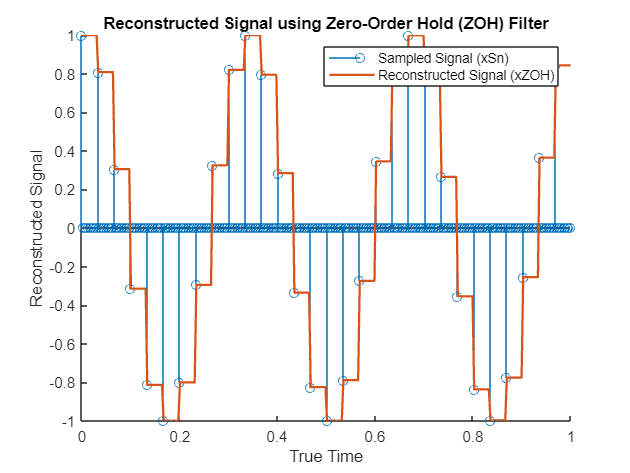

 % Define ZOH impulse response
 M = 10; % Number of subsampled ones
 Impulse_Response_of_ZOH = ones(1, M);
 % Convolve with the sampled signal to obtain the reconstructed signal
 xZOH = filter(Impulse_Response_of_ZOH, 1, xSn);
 % Define true time vector considering the sampling time
 true_time = linspace(0, Tmax, length(xZOH));
 % Plot the reconstructed signal versus true time
 figure;
 hold on;
 stem(true_time, xSn);
 plot(true_time, xZOH, 'LineWidth', 1.5);
 hold off;
 xlabel('True Time');
 ylabel('Reconstructed Signal');
 title('Reconstructed Signal using Zero-Order Hold (ZOH) Filter');
legend('Sampled Signal (xSn)', 'Reconstructed Signal (xZOH)');
 % Limit the plot to 3 cycles
 xlim([0, 3 * 1/f0]);

## Exercise 3 (First Order Hold)

This filter provides a more accurate approximation of the continuous-time signal compared to the ZOH interpolation by linearly interpolating between adjacent samples. The linear interpolation creates a smoother transition between samples, reducing the staircase effect introduced by the ZOH filter. Mathematically, the FOH filter output `y(t)` at any time `t` can be calculated as a weighted sum of the current sample `x[n]` and the previous sample `x[n-1]`, as shown in the equation:

`y(t) = (t - nTs) x[n] + ((n+1)Ts - t) x[n-1]`

where `n` is the integer index of the sample closest to time `t`. This equation essentially calculates the slope for the line segment connecting the two adjacent samples and uses it to estimate the signal value at any point between them.

**The impulse response of the FOH filter is a triangular pulse** with a duration of 2Ts, ranging from `-Ts` to `+Ts`. However, **unlike the ZOH filter, the FOH filter is anticausal**. An anticausal filter has a non-zero response before the input signal is applied (at negative time in this case). This property makes the FOH filter impractical for real-time applications where the filter output needs to be calculated based on present and past inputs only.

**To address this limitation and create a causal FOH filter suitable for real-time implementation, the impulse response is typically delayed by one sampling period.** This delay ensures that the filter output depends only on past and current samples. The code implements this by discarding the first `M-1` elements of the FOH response before convolution. These discarded elements correspond to the anticausal part of the filter.

**Advantages:**

- Reduces staircase approximation artifacts compared to ZOH.

- Provides smoother reconstruction by linear interpolation.

**Disadvantages:**

- Anti-causal impulse response, which is not practical for real-world implementation.

- Requires a delay to make it causal, leading to additional complexity.

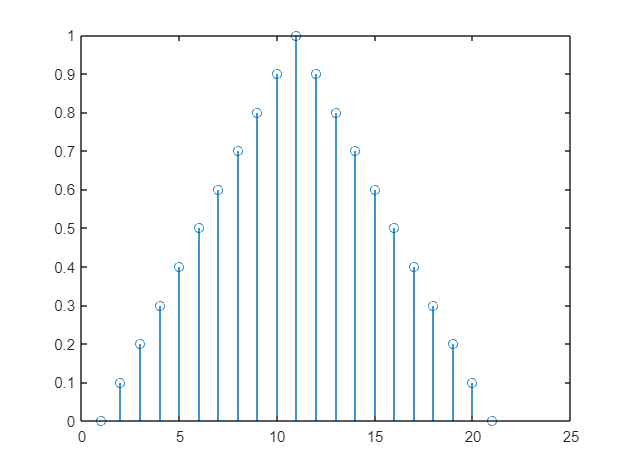

 % Define FOH impulse response
 figure;
 M = 10; % Number of elements
 T_s = 1/fs; % Sampling period
 foh_ir = [0:(1/M):1, 1-(1/M):-1/M:0]; % Triangular pulse
 stem(foh_ir)

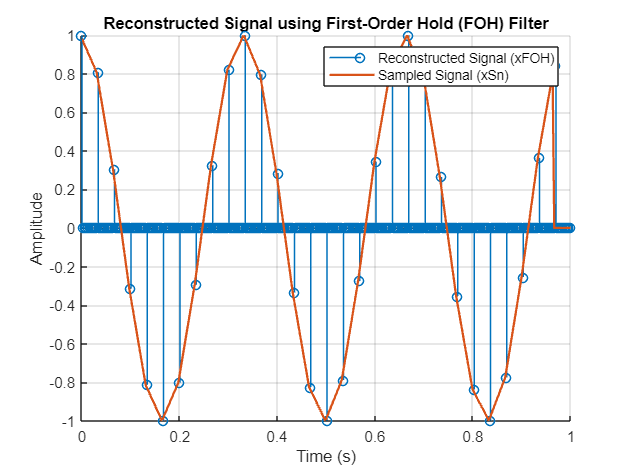

 % Convolve with the sampled signal to obtain the reconstructed signal
 xFOH = filter(foh_ir, 1, xSn);
 % Define true time vector considering the sampling time
 true_time = linspace(0, Tmax, length(xFOH));
 % Plot the reconstructed signal versus true time
 figure;
 hold on;
 %As there is a natural delay cause we want to make filter causal. 
%we now want to remove that delay from the result FOH
 xFOH = xFOH(12:end);
 xFOH = [xFOH, zeros(1, 11)];
 stem(true_time, xSn, 'LineWidth', 1); % Plot sampled signal
 plot(true_time, xFOH, 'LineWidth', 1.5); % Plot FOH output, starting from Mth sample
 hold off;
 xlabel('Time (s)');
 ylabel('Amplitude');
 title('Reconstructed Signal using First-Order Hold (FOH) Filter');
 legend('Reconstructed Signal (xFOH)', 'Sampled Signal (xSn)');
 grid on;

## Exercise 4 Applying Ideal Low Pass Filter

The ideal LPF theoretically achieves perfect reconstruction of the original signal under the condition that the** sampling frequency adheres to the Nyquist criterion**. This criterion states that the sampling frequency (f_s) must be greater than twice the highest frequency component (f_max) present in the signal (f_s > 2 * f_max). 

**The ideal LPF's impulse response is a sinc function**, which has the unique property of allowing perfect separation of the desired signal spectrum from its replicas created during the sampling process. These replicas, also known as images, appear due to the inherent periodicity introduced by sampling. The ideal LPF ideally blocks these unwanted images, preserving only the original signal spectrum within the bandwidth of interest (0 to f_s/2).

**However**, the ideal LPF is not realizable in practice due to two key limitations. **Firstly, its impulse response is infinitely long**, requiring an infinite number of filter taps for perfect implementation. This is infeasible for real-world systems with finite resources. **Secondly, the ideal LPF is anticausal**, meaning its response includes non-zero values before the input signal is applied. This characteristic makes it unsuitable for causal systems, where the filter output depends only on current and past inputs.

**The code employs a truncated sinc function to approximate the ideal LPF**. This truncation introduces ripples in the filter's frequency response, which can cause deviations in the reconstructed signal compared to the perfect reconstruction offered by the ideal case. **The length of the truncated sinc function is a critical factor, as a shorter truncation leads to more significant ripples**. These ripples can introduce in-band distortion in the desired signal spectrum and out-of-band leakage of unwanted image components, affecting the fidelity of the reconstructed signal

**Advantages:**

- Theoretically provides perfect reconstruction without distortion.

- Removes aliasing effects by suppressing high-frequency components.

**Disadvantages:**

- Theoretical idealization, which is difficult to achieve in practice.

- Requires a long impulse response, making it computationally expensive.

- Introduces delay due to its anti-causal nature, necessitating additional processing.

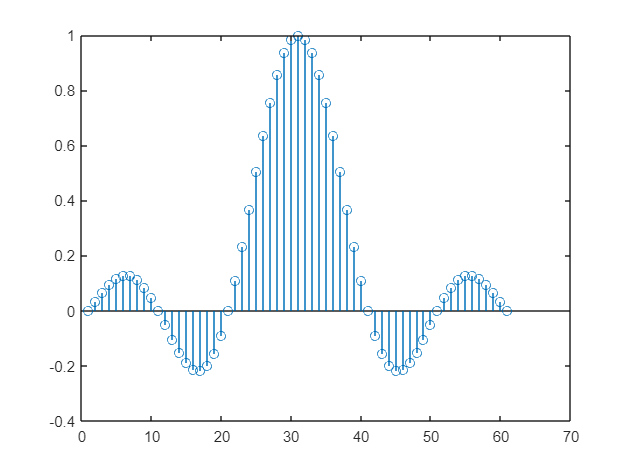

 % Define LPF impulse response
 figure;
 M = 10; % Number of samples per period
 T_s = 1/fs; % Sampling period
 N = 6 * M; % Length of LPF impulse response
 lpf_ir = sinc([-3*M:3*M]/M);
 stem(lpf_ir)

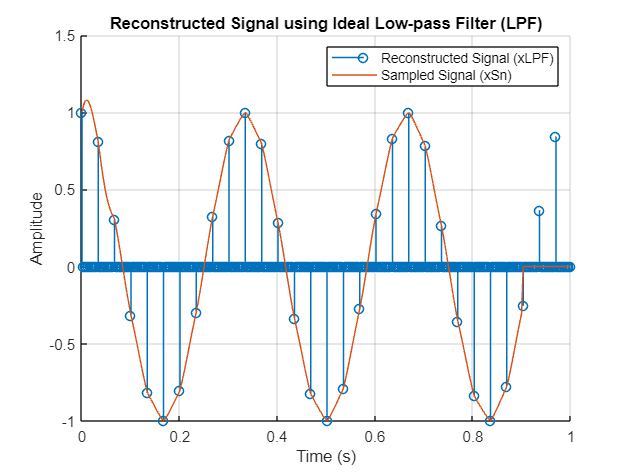


 %Convolve with the sampled signal to obtain the reconstructed signal
 xLPF = filter(lpf_ir, 1, xSn);
 % Define true time vector considering the sampling time
 true_time = linspace(0, Tmax, length(xLPF));
 % Plot the reconstructed signal versus true time
 figure;
 xLPF = xLPF(31:end);
 xLPF = [xLPF, zeros(1, 30)];
 hold on;
 stem(true_time, xSn, 'LineWidth', 1); % Plot sampled signal
 plot(true_time, xLPF); % Plot LPF output, starting from 6Mth sample
 hold off;
 xlabel('Time (s)');
 ylabel('Amplitude');
 title('Reconstructed Signal using Ideal Low-pass Filter (LPF)');
 legend('Reconstructed Signal (xLPF)', 'Sampled Signal (xSn)');
 grid on;

The choice of reconstruction filter hinges on the specific constraints and priorities of the application. Here's a breakdown of the key factors to consider:

- **Computational Complexity:** ZOH interpolation boasts the advantage of being the simplest to implement, making it attractive for resource-constrained scenarios. However, this simplicity comes at the cost of introducing staircase artifacts. FOH interpolation offers a step up in accuracy while still maintaining moderate complexity. Ideal LPFs represent the pinnacle of reconstruction fidelity, but their unrealizable nature necessitates practical LPF designs that can be implemented with finite resources. These practical designs often involve trade-offs between computational efficiency and achieving an acceptable level of distortion.

- **Reconstruction Accuracy:** If faithful reproduction of the original signal is paramount, ideal LPFs (in theory) or high-quality practical LPF designs become the preferred choices. These filters strive to minimize in-band distortion and suppress out-of-band image components, ensuring a reconstructed signal that closely resembles the original. However, computational complexity often scales with increasing accuracy.

- **Real-Time Constraints:** For applications demanding real-time processing, the filter's causality becomes a crucial factor. ZOH and causal FOH filters are well-suited for real-time scenarios due to their reliance only on current and past samples. Ideal LPFs, being anticausal, are not applicable in real-time systems. Practical LPF designs should also be evaluated for their suitability in real-time constraints, considering factors like filter complexity and potential delays introduced.

In essence, the selection of a reconstruction filter involves finding a sweet spot that balances the application's requirements for accuracy, computational efficiency, and real-time constraints.